clear all

%% Time Domain: 
% mention the time domain for which u want to run the ODE. 
domain = [0 500];

high=0;
low=0;
inter=0;
% You need to change the parameters here too
%Degradation rate
gamma_A = 1.2; 
gamma_B = 0.5; 
% Transcription rate/ Production rate:
g_A = 10; 
g_B = 10; 



%% Starting the loop for a inital conditions:
for i=1:1:200
    A = 10*rand(1); 
    B = 10*rand(1); 
    %% In general, you can generate N random numbers in the 
    %% interval (a,b) with the formula r = a + (b-a).*rand(N,1).
    
%% Calling ODE function:

    [t, x] = ode45(@(t,x) interactions(t,x),domain,[A;B]);
    %Ploting:
    plot(t,x(:,1)/(g_A/gamma_A), 'LineWidth', 2, 'DisplayName', 'A'); 
    hold on;
    
    
    if x(end)>=150
        high=high+1;
    
    elseif x(end) <=60
        low=low+1;
    else 
        inter=inter+1;
    end

end
combine=low+high;
disp("High + Low= "+combine+', Hybrid= '+inter);

High + Low= 200, Hybrid= 0


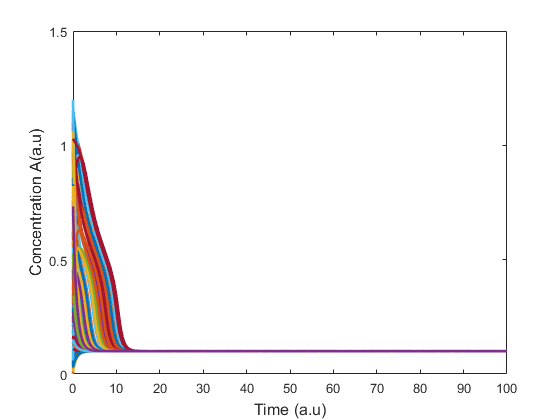

%% Adding feature to the plot:
% gcf % get current figure:
xlim([0 100]);
ylim([0 1.5]);
xlabel('Time (a.u)',"FontSize",12,"FontName",'Arial','FontWeight','bold');
ylabel('Concentration A(a.u)',"FontSize",12,"FontName",'Arial','FontWeight','bold');


hold off 

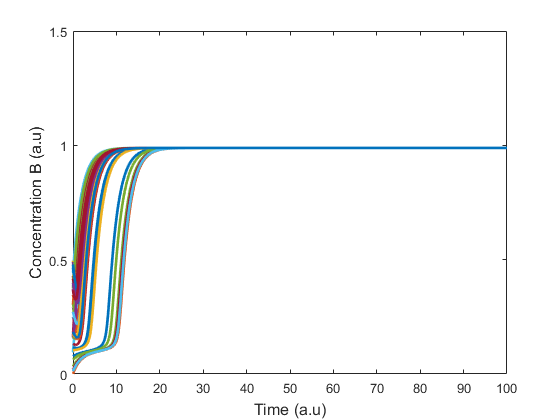


for i=1:1:50
    A = 10*rand(1); 
    B = 10*rand(1); 
    %% In general, you can generate N random numbers in the 
    %% interval (a,b) with the formula r = a + (b-a).*rand(N,1).
    
%% Calling ODE function:

    [t, x] = ode45(@(t,x) interactions(t,x),domain,[A;B]);
    %Plotting:
    plot(t,x(:,2)/(g_B/gamma_B), 'LineWidth', 2, 'DisplayName', 'B');
    hold on;
    
    
end
xlim([0 100]);
ylim([0 1.5]);
xlabel('Time (a.u)',"FontSize",12,"FontName",'Arial','FontWeight','bold');
ylabel('Concentration B (a.u)',"FontSize",12,"FontName",'Arial','FontWeight','bold');

Defining the Local functions used for the plotting

% hill function

function H = hill(X,X0,lambda,n)
% H+ 
H1 = (X^n)/(X0^n+X^n);
% H-
H2 = (X0^n)/(X0^n+X^n);

% Hill function =  H- plus (lambda)* H+
H = H2 + lambda*H1;

end


function dxdt = interactions(t,x)

% defining array of values for the time t: 
dxdt = zeros(2,1);

%% Paramaters
% Degradation rate:
gamma_A = 1.2;   gamma_B = 0.5;  

% Transcription rate/ Production rate:
g_A = 10; 
g_B = 10;   

% Hills function threshold :
A0B = 2;
B0A = 2;
A0A = 10;   B0B = 10;

% Cooperativity/ hill function coeSfficient:
nAtoB = 5;   nBtoA = 5;
nAtoA = 3;   nBtoB = 3;

% fold change/ lambda
lambda_AtoB = 0.1;   lambda_BtoA = 0.1;
lambda_AtoA = 3;   lambda_BtoB = 3;

% %% equations:
% dxdt(1) = g_A*hill(x(1),A0A,lambda_AtoA,nAtoA)*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1);  %% equation A
% dxdt(2) = g_B*hill(x(2),B0B,lambda_BtoB,nBtoB)*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2); % equation B
% end
% % equations:
dxdt(1) = g_A*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
dxdt(2) = g_B*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
end
